load gTruth.mat

if ~isfolder(fullfile("TrainingDataCustomMultiDetect"))
    mkdir TrainingDataCustomMultiDetect
end

trainingData1 = objectDetectorTrainingData(gTruth, 'SamplingFactor',1,... 
    'WriteLocation', 'TrainingDataCustomMultiDetect');

Write images extracted for training to folder: 
    TrainingDataCustomMultiDetect

Writing 44 images extracted from output.avi...Completed.


trainingData = [trainingData1];

trainingData(1:4,:)

ans = 4×2 table
                      imageFilename                           cone     
    __________________________________________________    _____________

    {'TrainingDataCustomMultiDetect\output1_0037.png'}    {10×4 double}
    {'TrainingDataCustomMultiDetect\output1_0073.png'}    { 4×4 double}
    {'TrainingDataCustomMultiDetect\output1_0100.png'}    { 4×4 double}
    {'TrainingDataCustomMultiDetect\output1_0149.png'}    { 4×4 double}



rng(0);

shuffledIndices = randperm(height(trainingData));
idx = floor(0.8 * length(shuffledIndices));
trainingIdx = 1:idx;
testIdx = trainingIdx(end)+1: length(shuffledIndices);

trainingDataset = trainingData(shuffledIndices(trainingIdx),:);
testDataSet = trainingData(shuffledIndices(testIdx),:);

inputSize = [720 1280 3];
inputLayer = imageInputLayer(inputSize, 'Name','input','Normalization','none');

filterSize = [3 3];

middlelayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1, 'Name', 'conv_1',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN1')
    reluLayer('Name', 'relu_1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1, 'Name', 'conv_2',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN2')
    reluLayer('Name', 'relu_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1, 'Name', 'conv_3',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1, 'Name', 'conv_4',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN4')
    reluLayer('Name', 'relu_4')
    ];
lgraph = layerGraph([inputLayer; middlelayers]);
numClasses = size(trainingData,2)-1;

trainingData11 = boxLabelDatastore(trainingData(:,2:end));

numAnchors = 10;
[anchorBoxes,meaIoU] = estimateAnchorBoxes(trainingData11,numAnchors);

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,lgraph,'relu_4');


*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* cone

Checking training data...done.
Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:18 |        34.96 |       1222.4 |          0.0010 |
|      25 |          50 |       00:08:46 |         3.44 |         11.8 |          0.0010 |
|      50 |         100 |       00:16:43 |         3.36 |         11.3 |          0.0010 |
|      75 |         150 |       00:23:50 |         3.47 |         12.0 |          0.0010 |
|     100 |         200 |       00:31:17 |         3.21 |        

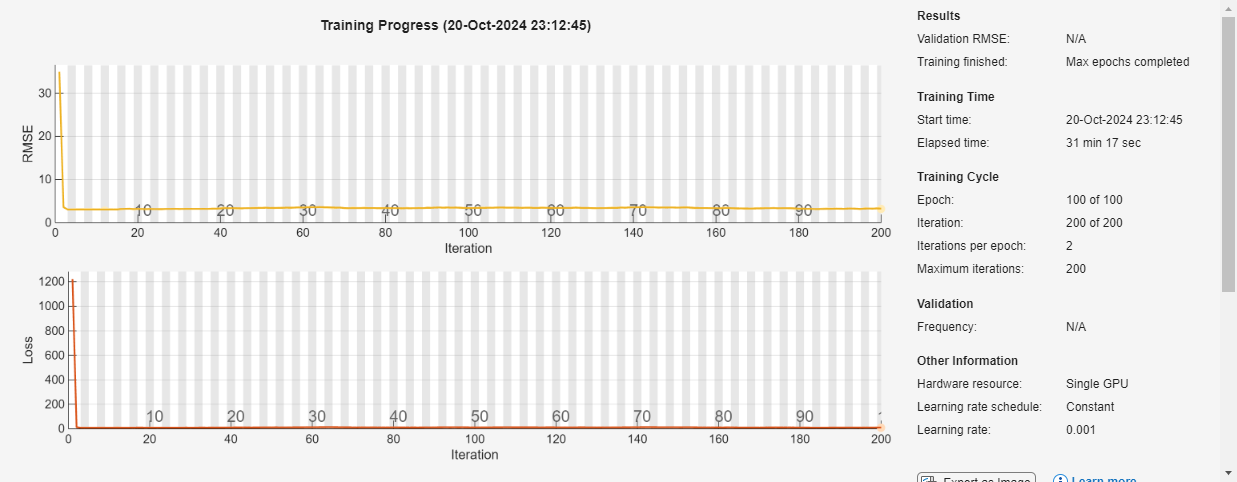


doTraining = true;

if doTraining
    rng(0);

    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'Verbose', true, ...
        'MiniBatchSize', 16,...
        'MaxEpochs',100, ...
        'Shuffle','every-epoch', ...
        'VerboseFrequency', 50, ...
        'ExecutionEnvironment', 'auto',...
        'Plots',"training-progress");
    [yolov2ObjectDetector, info] = trainYOLOv2ObjectDetector(trainingDataset,lgraph,options);
    class=yolov2ObjectDetector;
    save('yolov2ConeDetector.mat','class')
else
    load('yolov2ConeDetector.mat');
end